1.曲 线 图

Matlab作图是通过描点、连线来实现的，故在画一个曲线图形之前，必须先取得该图形上的一系列的点的坐标（即横坐标和纵坐标），然后将该点集的坐标传给Matlab函数画图. 

命令为：    PLOT(X,Y,S)

X,Y是向量,分别表示点集的横坐标和纵坐标 S表示线型

plot绘图函数的叁数 

　	字元 	颜色	字元 	图线型态

　	y 	黄色	. 	点

　	k 	黑色	o 	圆

　	w 	白色	x 	x

　	b 	蓝色	+ 	+

　	g 	绿色	* 	*

　	r 	红色	- 	实线

　	c 	亮青色	: 	点线

　	m 	锰紫色	-. 	点虚线

　	　	　	-- 	虚线

PLOT(X,Y)--画实线

PLOT(X,Y1,S1,X,Y2,S2,……,X,Yn,Sn)--将多条线画在一起

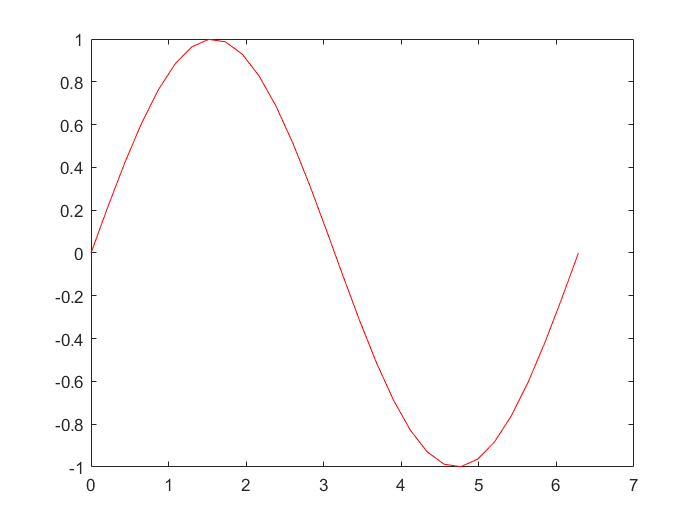

clc;
clear;
close all;
x=linspace(0,2*pi,30);
y=sin(x);
plot(x,y,'r')

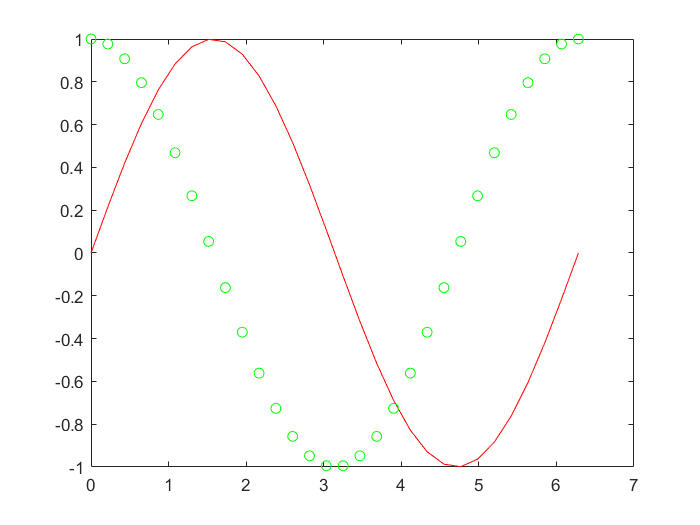


x=linspace(0,2*pi,30);
y=sin(x);
z=cos(x);
plot(x,y,'r',x,z,'go')

**2.**`符号函数`**(**`显函数、隐函数和参数方程`**)**`画图`

**(1) ezplot**

1`、`ezplot(‘f(x)’,[a,b])       

     `表示在`a<x<b`绘制显函数`f=f(x)`的函数图`

2`、`ezplot(‘f(x,y)’,[xmin,xmax,ymin,ymax])    

  `表示在区间`xmin<x<xmax`和`ymin<y<ymax`绘制隐函数`f(x,y)=0`的函数图`

3`、`ezplot(‘x(t)’,’y(t)’,[tmin,tmax])         `表示在区间`tmin<t<tmax

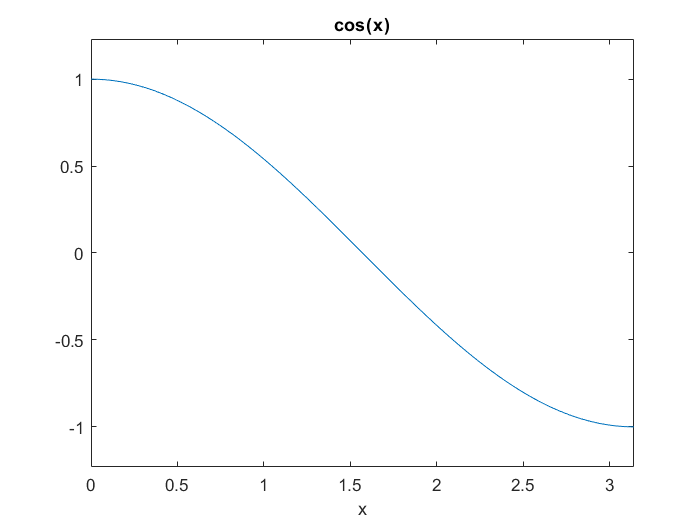

ezplot('cos(x)',[0,pi])

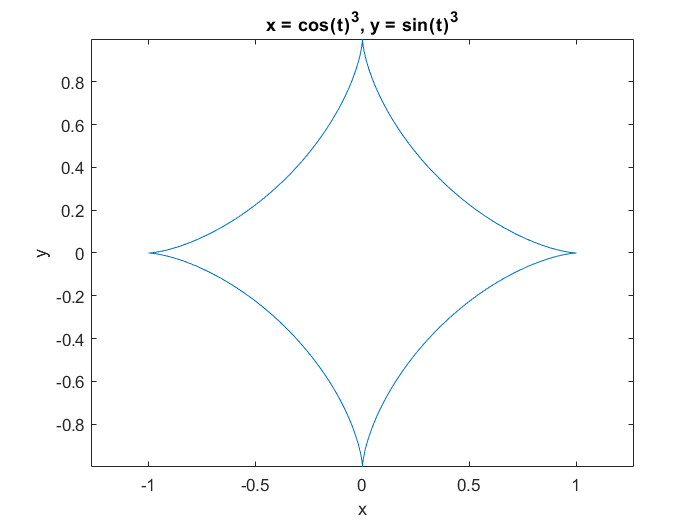


ezplot('cos(t)^3','sin(t)^3',[0,2*pi])%在[0,2*pi]画星形图

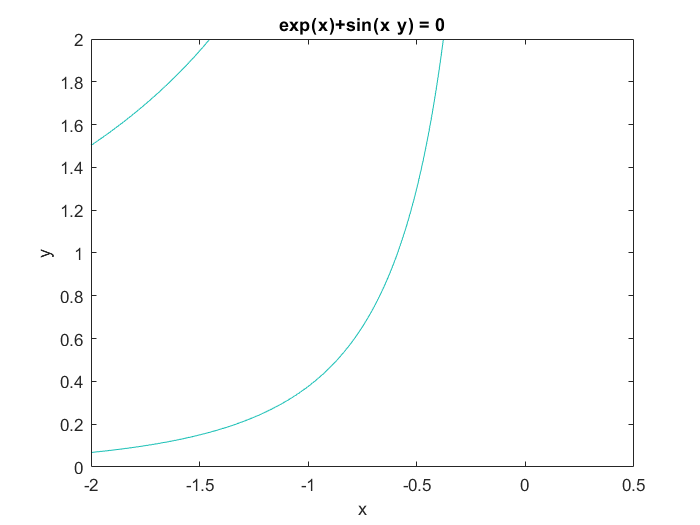


ezplot('exp(x)+sin(x*y)',[-2,0.5,0,2]) %在[-2，0.5]，[0，2]上画隐函数

**(2) fplot**

**fplot(‘fun’,lims)**   

   `表示绘制字符串`fun`指定的函数在`lims=[xmin,xmax]`的图形`.

`注意：`

[1] fun`必须是`M`文件的函数名或是独立变量为`x`的字符串`.  

[2] fplot`函数不能画参数方程和隐函数图形，但在一个图上可以画多个图形。`

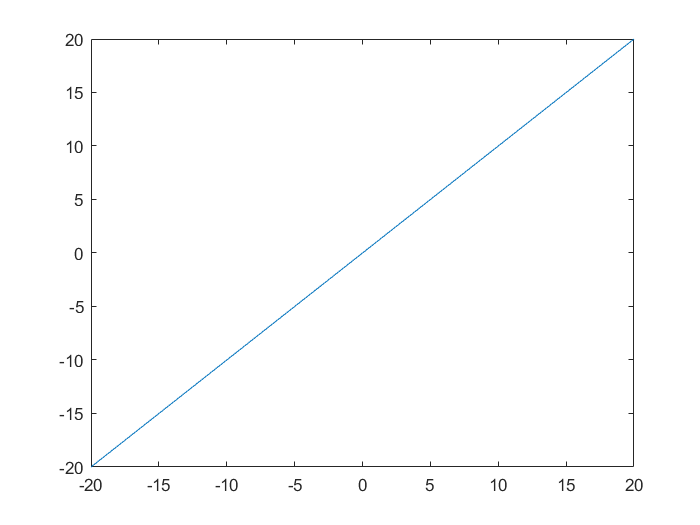



fplot('myfun',[-20,20]);

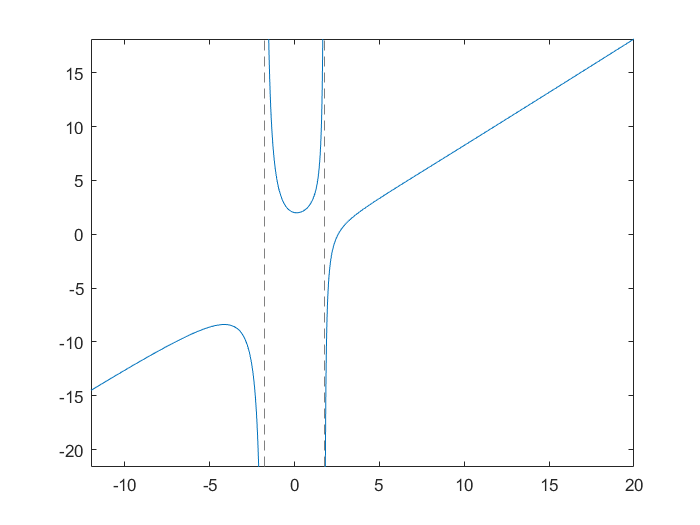

fh=@fun1;
fplot(fh,[-12,20]);

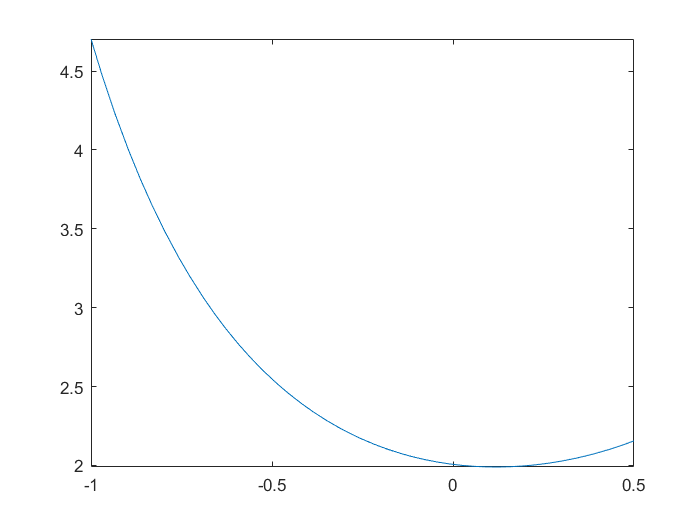


%句柄对于初学者来说概念新，简单的讲它能使一个标示符，如matlab中fplot函数fh=@myfun中的fh具有一种功能，代表函数myfun,
% %如果不用句柄，一般是这样的：
fplot('fun1',[-1,0.5])

## `三`  `维`   `图`   `形`

# **1**`、空间曲线`

PLOT3(x,y,z,s)

n`维向量，`x,y,z`分别表示曲线上点集的横坐标、纵坐标、函数值`s`指定颜色、线形等`

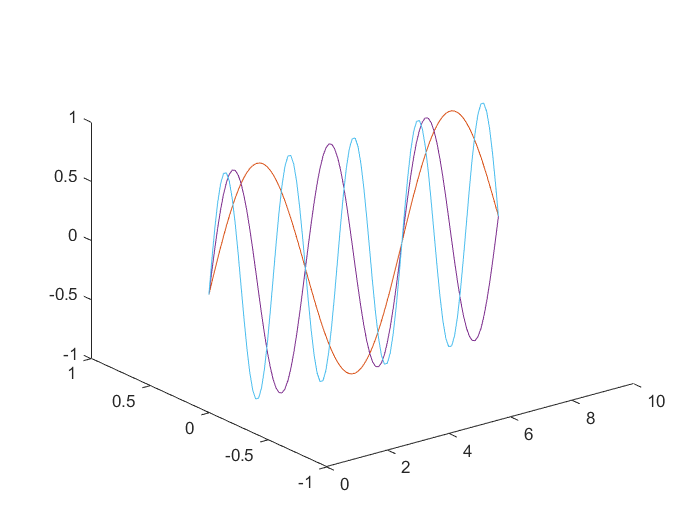

x=linspace(0,3*pi); % 0到 3pi 间100个数据点
z1=sin(x);  
z2=sin(2*x);
z3=sin(3*x);
y1=zeros(100);  %  含有100个数据的 0数组
y3=zeros(100);  
y2=y3/2;
plot3(x,y1,z1,x,y2,z2,x,y3,z3);

%正弦曲线图


**2**`、多条曲线`

**PLOT3(x,y,z)**

`其中`**x**`，`**y**`，`**z**`是都是`**m*n**`矩阵，其对应的每一列表示一条曲线`

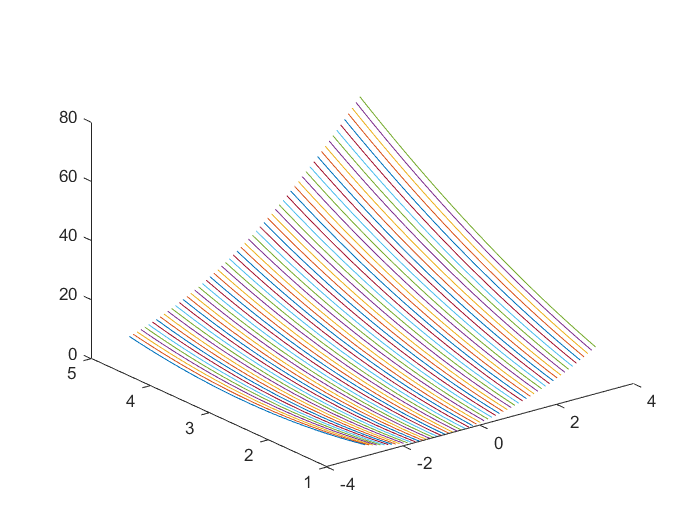

x=-3:0.1:3;y=1:0.1:5;
[X,Y]=meshgrid(x,y);
Z=(X+Y).^2;
plot3(X,Y,Z)

%meshgrid(x,y)的作用是产生一个以向量x为行、向量y为列的矩阵.  详细情况在变量区看规律

# **2**`、空`  `间`  `曲`  `面`

**(1)**  **surf(x,y,z)** `画出数据点（`**x**`，`**y**`，`**z**`）表示的曲面`

**x,y,z**`数据矩阵。分别表示数据点的横坐标、纵坐标、函数值`

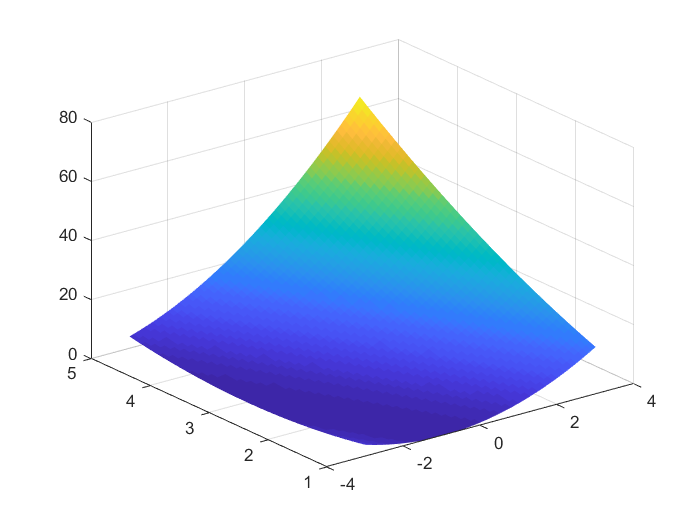

x=-3:0.1:3;   % 在X轴上取点 
y=1:0.1:5;      % 在Y轴上取点
[X,Y]=meshgrid(x,y);
Z=(X+Y).^2;   %计算函数值
surf(X,Y,Z)
shading flat    %将当前图形变得平滑

`（`**2**`）`**Mesh(x,y,z) **    `画网格曲面`

`数据矩阵。`**x,y,z**`分别表示数据点的横坐标、纵坐标、函数值`

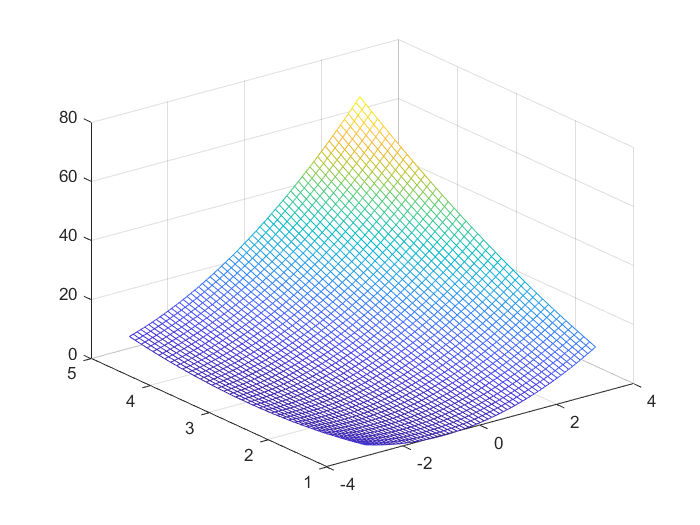

x=-3:0.1:3;   y=1:0.1:5;
[X,Y]=meshgrid(x,y);
Z=(X+Y).^2;
mesh(X,Y,Z) 

`剔透玲珑球`

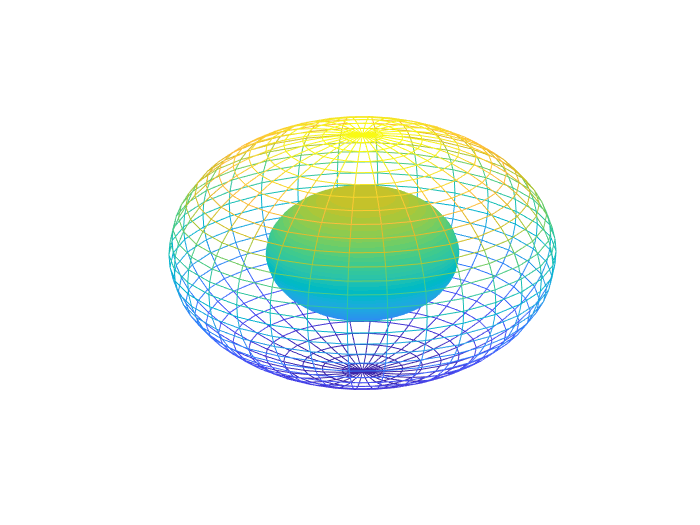

[X0,Y0,Z0]=sphere(30); %产生单位球面的三维坐标
X=2*X0;Y=2*Y0;Z=2*Z0; %产生半径为2的球面的三维坐标
surf(X0,Y0,Z0);       %画单位球面
shading interp        %采用插补明暗处理
hold on; mesh(X,Y,Z);hold off%画外球面
hidden off            %产生透视效果
axis off              %不显示坐标轴

**(3)****meshz(X,Y,Z)** `在网格周围画一个`**curtain**`图`**(**`如`**,**`参考平面`**)**

`例`  `绘`**peaks**`的网格``（`**peaks**`为`**MATLAB**`提供的典型三维曲面）`

`输入命令`**:**

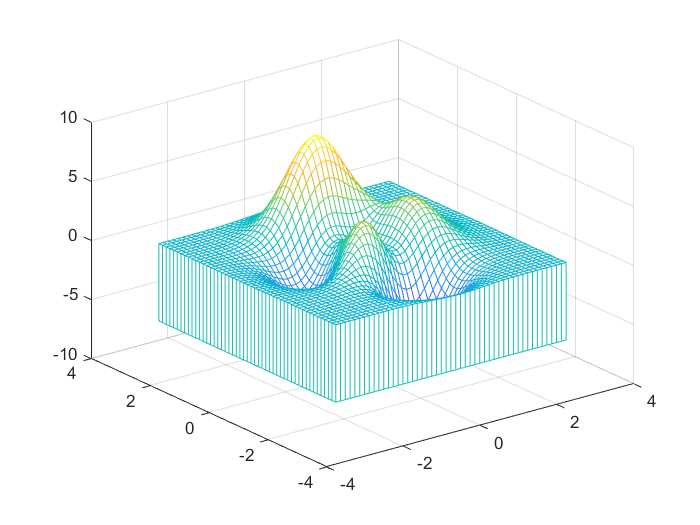

[X,Y]=meshgrid(-3:.125:3);
Z=peaks(X,Y);
meshz(X,Y,Z)

`处`  `理`  `图`  `形`

**1**`、在图形上加``分格线``、图例和标注`

`（`**1**`）`**GRID ON****: **`加分格线在当前图上`

    **GRID OFF****: **`删除分格线`

`（`**2**`）`**hh = xlabel(string)****:** `在当前图形的`**x**`轴上加图例`**string**

**hh = ylabel(string)****:** `在当前图形的`**y**`轴上加图例`**string**

     **hh = zlabel(string)****:**`在当前图形的`**z**`轴上加图例`**string**

     **hh = title(string)****:**`在当前图形的顶端上加图例`**string**

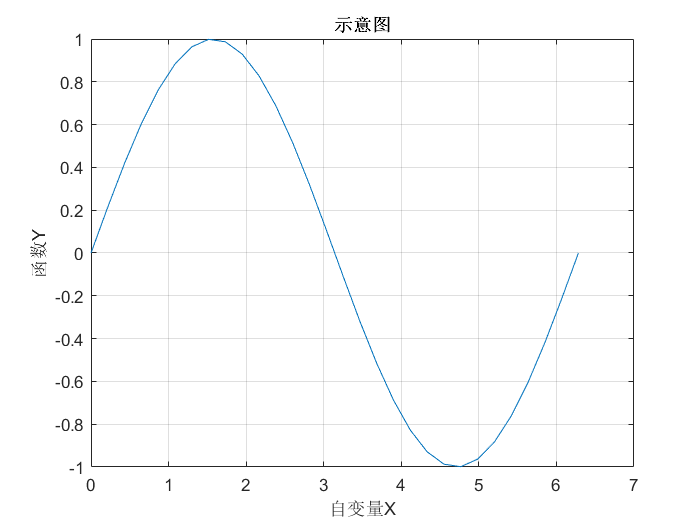

%在区间[0,2*pi]画sin(x)的图形，并加注图例“自变量X”、“函数Y”、“示意图”, 并加分格线.
%输入命令:
x=linspace(0,2*pi,30);
 y=sin(x);
 plot(x,y)
 xlabel('自变量X')
 ylabel('函数Y')
 title('示意图')
 grid on   %画分格线

 **hh = gtext(‘string’)**

`命令`**gtext(‘string’)**`用鼠标放置标注在现有的图上`**.**`运行命令`**gtext(‘string’)**`时，屏幕上出现当前图形，在图形上出现一个交叉的十字，该十字随鼠标的移动移动，当按下鼠标左键时，该标注`**string**`放在当前十交叉的位置`**. **

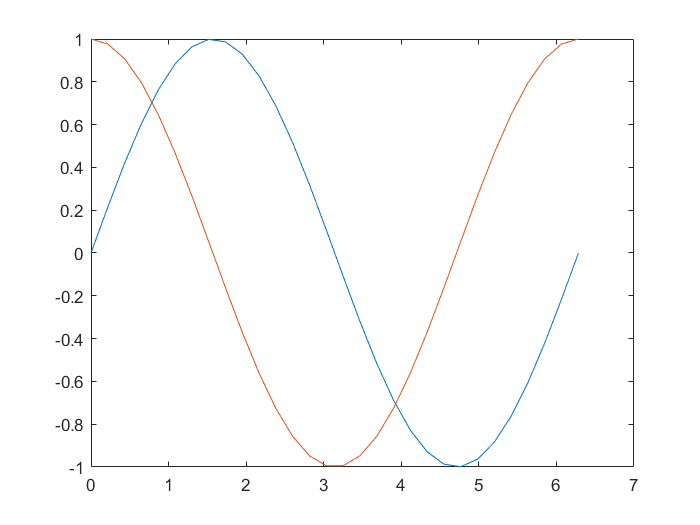

%在区间[0,2*pi]画sin(x)，并分别标注“sin(x)” “cos(x)”.
%输入命令:
x=linspace(0,2*pi,30);
y=sin(x);
z=cos(x);
plot(x,y,x,z)

%gtext('sin(x)');会弹出窗口选择位置
%gtext('cos(x)');


**2**`、定制坐标`

**Axis([xmin xmax ymin ymax zmin zmax])** 

`定制图形坐标`

**xmin xmax ymin ymax zmin zmax** 

**x**`、`**y**`、`**z**`的最大、最小值`**Axis auto**   `将坐标轴返回到自动缺省值`

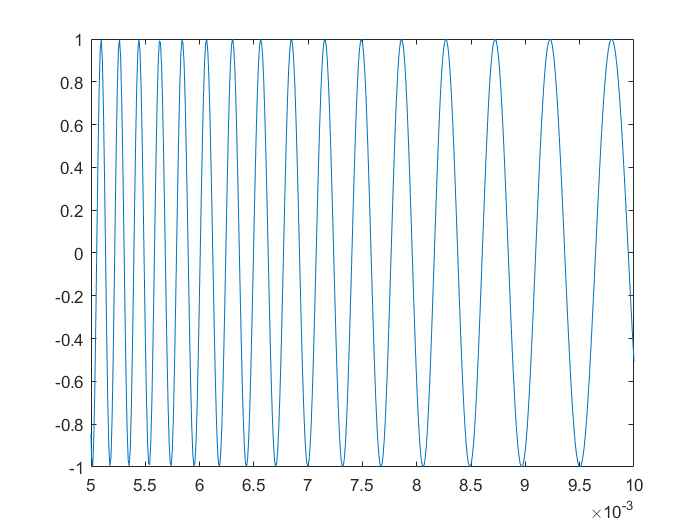

x=linspace(0.0001,0.01,1000);
y=sin(1./x);
plot(x,y)
axis([0.005 0.01 -1 1])

`图形保持`

**(1) hold on**  `保持当前图形`**, **`以便继续画图到当前图上`

**hold**  **of**   `释放当前图形窗口`

**figure(h)** `新建`**h**`窗口，激活图形使其可见，并把它置于其它图形之上`

`例`**5 **`区间`**[0,2*pi]**`新建两个窗口分别画出`**y=sin(x)**`；`**z=cos(x)**`。`

`输入命令`**:**

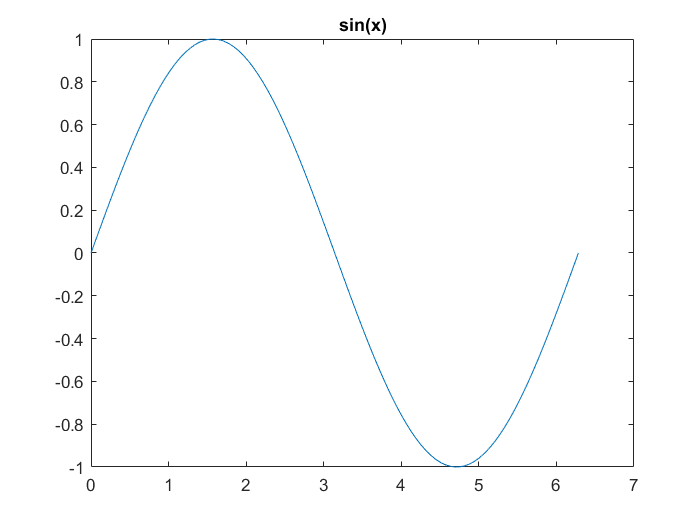


x=linspace(0,2*pi,100);
y=sin(x);z=cos(x);
plot(x,y);
title('sin(x)');

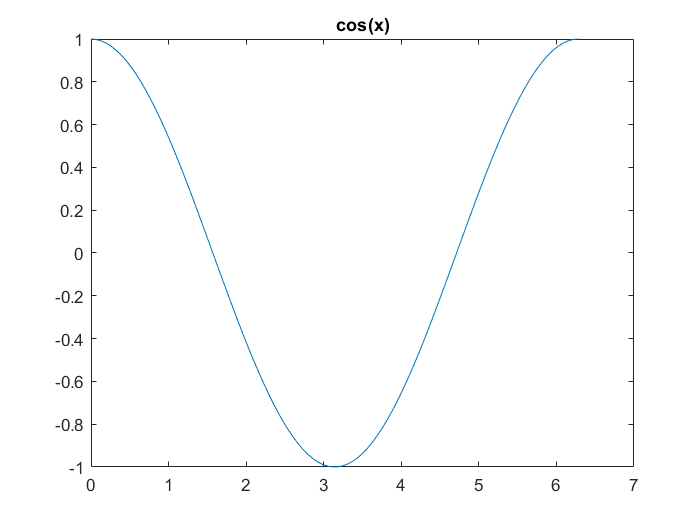

%pause   %暂停
figure(2);
plot(x,z);
title('cos(x)');

**4**`、分割窗口`

**h=subplot(mrows,ncols,thisplot)**

`划分整个作图区域为`**mrows*ncols**`块（逐行对块访问）并激活第`**thisplot**`块，其后的作图语句将图形画在该块上。`

**subplot(mrows,ncols,thisplot)**

`激活已划分为`**mrows*ncols**`块的屏幕中的第`**thisplot**`块，其后的作图语句将图形画在该块上。`

**subplot(1,1,1)**

`命令`**Subplot(1,1,1)**`返回非分割状态。`

`例`**6 **`将屏幕分割为四块，并分别画出`**y=sin(x)**`，`**z=cos(x)**`，`**a=sin(x)*cos(x),b=sin(x)/cos(x)**`。`

`输入命令`**:**

x=linspace(0,2*pi,100);
 y=sin(x); z=cos(x);   
 a=sin(x).*cos(x);b=sin(x)./(cos(x)+eps)

b =          0    0.0636    0.1276    0.1927    0.2595    0.3284    0.4003    0.4760    0.5564    0.6427    0.7363    0.8391    0.9535    1.0827    1.2309    1.4043    1.6117    1.8664    2.1897    2.6175    3.2160    4.1221    5.6713    8.9666   20.9926  -63.0201  -12.5786   -6.9552   -4.7792   -3.6170   -2.8893   -2.3874   -2.0177   -1.7321   -1.5031   -1.3140   -1.1541   -1.0160   -0.8947   -0.7864   -0.6884   -0.5987   -0.5155   -0.4376   -0.3640   -0.2936   -0.2259   -0.1600   -0.0955   -0.0317


 subplot(2,2,1);plot(x,y),title('sin(x)')
 subplot(2,2,2);plot(x,z),title('cos(x)')
 subplot(2,2,3);plot(x,a),title('sin(x)cos(x)')
 subplot(2,2,4);plot(x,b),title('sin(x)/cos(x)')

`缩放图形`

**zoom**  **on**  `为当前图形打开缩放模式`

`单击鼠标左键，则在当前图形窗口中，以鼠标点中的点为中心的图形放大`**2**`倍；单击鼠标右键，则缩小`**2**`倍`

**zoom**  **off**  `关闭缩放模式`

`改变视角`**view**

`（`**1**`）`**view(a,b)**   `改变视角到`**(a,b),a**`是方位角`**,b**`为仰角。缺省视角为（`**-37.5**`，`**30**`）。`

`（`**2**`）`**view**`（`**[x**`，`**y**`，`**z]**`）`

**view**`用空间矢量表示的，三个量只关心它们的比例，与数值的大小无关，`**x**`轴`**view**`（`**[1**`，`**0**`，`**0]**`），`**y**`轴`**view**`（`**[0**`，`**1**`，`**0]**`），`**z**`轴`**view**`（`**[0**`，`**0**`，`**1]**`）。`

`例`**7**`画曲面`**Z=(X+Y).^2**`在不同视角的网格图`**. **

`输入命令`**:**

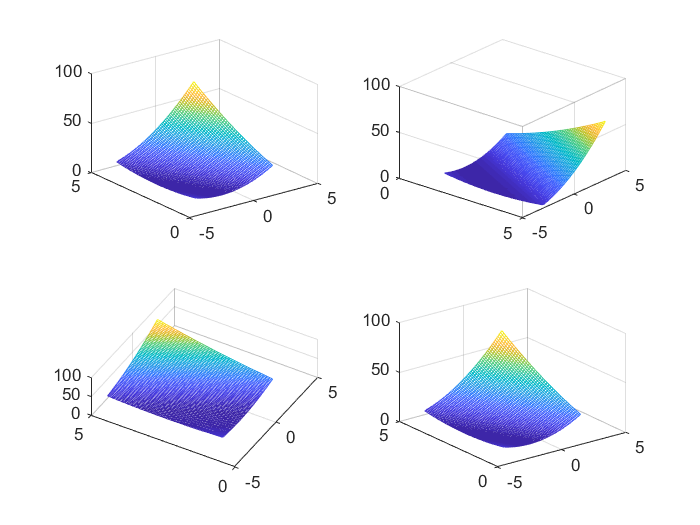

Error using view (line 51)
First argument must be a scalar axes handle

x=-3:0.1:3;   y=1:0.1:5;
[X,Y]=meshgrid(x,y);
Z=(X+Y).^2;
subplot(2,2,1); mesh(X,Y,Z)
subplot(2,2,2);mesh(X,Y,Z);view(50,-34)
subplot(2,2,3);mesh(X,Y,Z);view(-60,70) 
subplot(2,2,4);mesh(X,Y,Z);view(0,1,1)

 `动画`

**Moviein(),getframe,movie()**

`函数`**Moviein()**`产生一个帧矩阵来存放动画中的帧；函数`**getframe**`对当前的图象进行快照；函数`**movie()**`按顺序回放各帧。`

`例`**8 **`将曲面`**peaks**`做成动画。`** （放进来不能显示动画只能显示一张张图片，别随便运行，卡死了，动画部分代码复制粘贴到m文件或者命令行去运行！放进来不能显示动画只能显示一张张！！！）**

`输入命令`**:**

[x,y,z]=peaks(30);

surf(x,y,z)

axis([-3 3 -3 3 -10 10])

%axis off

%shading interp

%colormap(hot)

m=moviein(15);

for i=1:15

   view(-37.5+24*(i-1),30)

   m(:,i)=getframe;

end

movie(m)

`彗星状轨迹图`

`例``9``简单二维示例。（请指令窗中运行以下指令）`**（放进来不能显示动画只能显示一张张图片，别随便运行，卡死了，动画部分代码复制粘贴到m文件或者命令行去运行！放进来不能显示动画只能显示一张张！！！）**

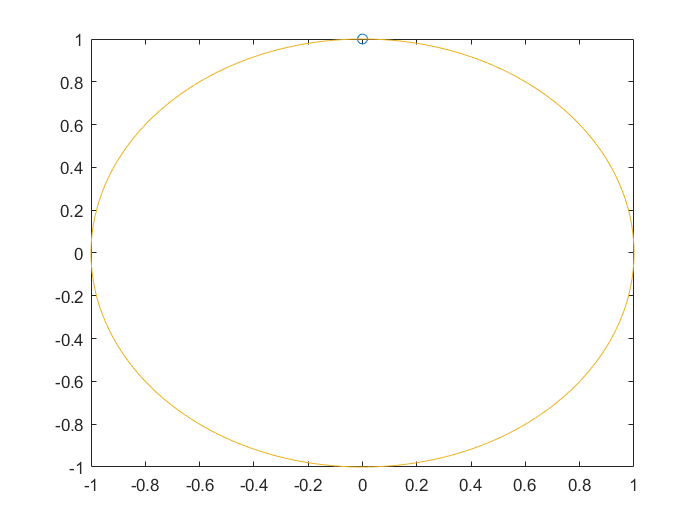

clc;
clear
close
n=10;
t=n*pi*(0:0.0005:1);
x=sin(t);y=cos(t);
plot(x,y,'g'); 
hold on;
comet(x,y,0.02);  %彗星状轨迹图0.02视角
hold off

`【``*``例】卫星返回地球的运动轨线示意。`

R0=1;                    %以地球半径为一个单位
a=12*R0;b=9*R0;T0=2*pi;   %T0是轨道周期
T=5*T0;dt=pi/100;t=[0:dt:T]';
f=sqrt(a^2-b^2);   %地球与另一焦点的距离
th=12.5*pi/180;      %卫星轨道与x-y平面的倾角
E=exp(-t/20);            %轨道收缩率
x=E.*(a*cos(t)-f);y=E.*(b*cos(th)*sin(t));
z=E.*(b*sin(th)*sin(t));
plot3(x,y,z,'g')                       %画全程轨线
[X,Y,Z]=sphere(30);X=R0*X;Y=R0*Y;Z=R0*Z;      %获得单位球坐标
grid on,hold on,surf(X,Y,Z),shading interp    %画地球
x1=-18*R0;x2=6*R0;y1=-12*R0;y2=12*R0;z1=-6*R0;z2=6*R0;
axis([x1 x2 y1 y2 z1 z2])           %确定坐标范围
view([117 37]),comet3(x,y,z,0.02),hold off        %设视角、画运动轨线  

特殊二、三维图形

一、特殊二维图形

1、极坐标图：

polar (theta,rho,s) 用角度theta（弧度表示）和极半径rho作极坐标图，用s指定线型。

例1 

输入命令:

theta=linspace(0,2*pi),                         

theta =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


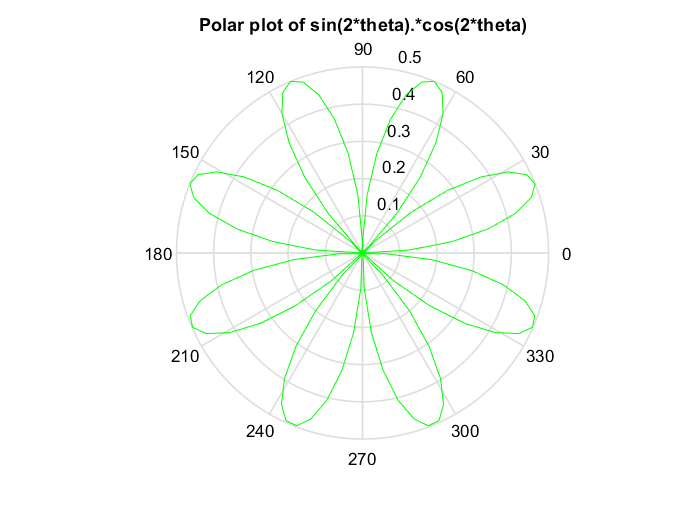

rho=sin(2*theta).*cos(2*theta);
polar(theta,rho,'g')
title('Polar plot of sin(2*theta).*cos(2*theta)');

2、散点图:  

scatter（X,Y,S,C）

在向量X和Y的指定位置显示彩色圈．X和Y必须大小相同．

例2  绘制seamount散点图

输入命令:

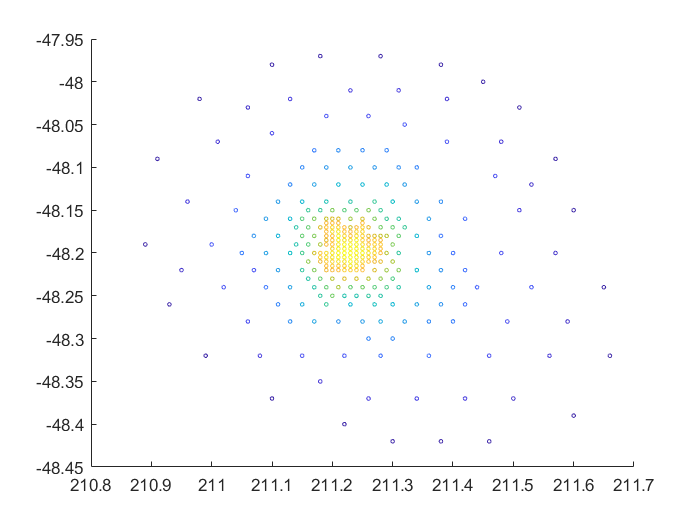

load seamount  %从MAT文件中读取变量
scatter(x,y,5,z)

3、平面等值线图： 

contour (x,y,z,n) 绘制n个等值线的二维等值线图

例3  在范围-2<x<2,-2<y<3内绘 的等值线图

输入命令:

[X,Y]=meshgrid(-2:.2:2,-2:.2:3);
Z=X.*exp(-X.^2-Y.^2);
[C,h]=contour(X,Y,Z);
clabel(C,h)     %沿线标识
colormap cool  %青紫调冷色图

4、MATLAB还有其他各种二维绘图函数，以适合不同的应用，详见下表。 

小整理：其他各种二维绘图函数 

　	bar 	长条图

　	errorbar 	图形加上误差范围 

　	fplot 	较精确的函数图形 

　	polar 	极座标图

　	hist 	累计图

　	rose 	极座标累计图

　	stairs 	阶梯图

　	stem 	针状图

　	fill 	实心图

　	feather 	羽毛图

　	compass 	罗盘图

　	quiver 	向量场图

1、	当资料点数量不多时，长条图是很适合的表示方式： 

); %rand产生均匀随机数size矩阵大小

bar(x,y); 

2、stairs可画出阶梯图：

例  bar(x,y) 可画出长条图

close all; % 关闭所有的图形视窗 

x=1:10; 
y=rand(size(x))

y =     0.6324    0.0975    0.2785    0.5469    0.9575    0.9649    0.1576    0.9706    0.9572    0.4854


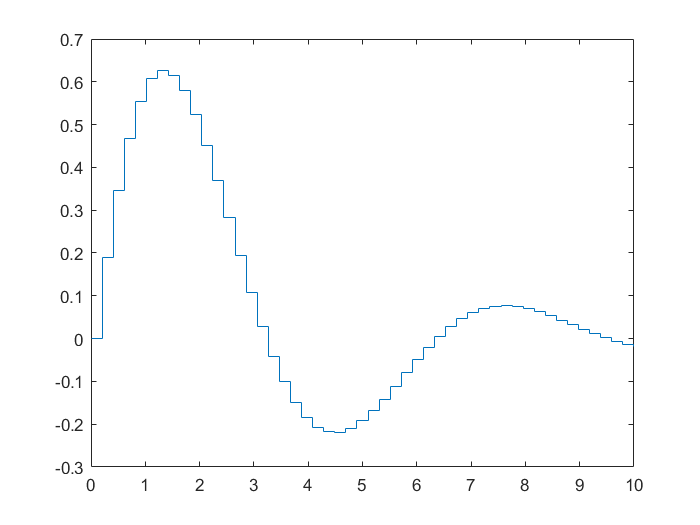

x=linspace(0,10,50); 
y=sin(x).*exp(-x/3); 
stairs(x,y); 

3、stems产生针状图，常被用来绘制数位讯号： 

例  

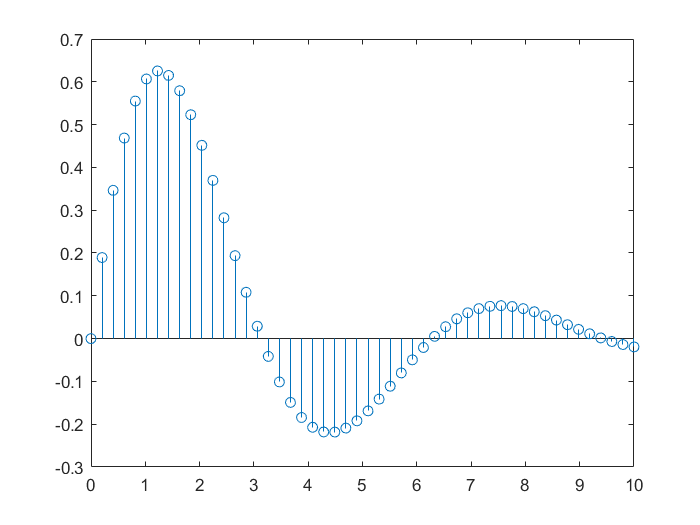

x=linspace(0,10,50); 
y=sin(x).*exp(-x/3); 
stem(x,y); 

4、fill实心图，将资料点视为多边行顶点，并将此多边行涂上颜色： 

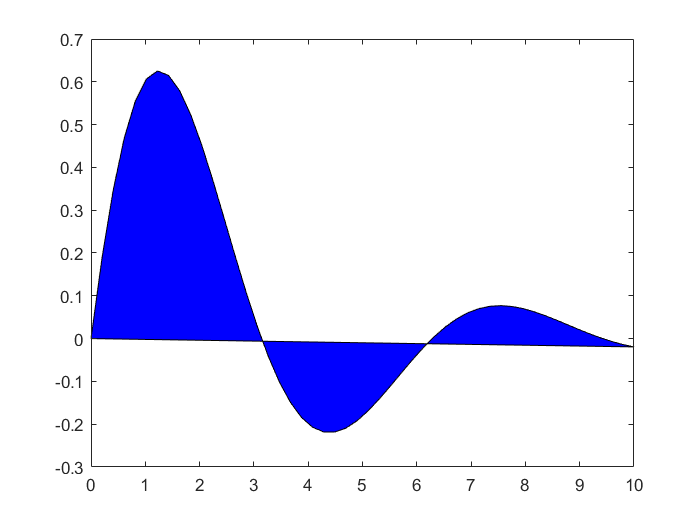

x=linspace(0,10,50); 
y=sin(x).*exp(-x/3); 
fill(x,y,'b'); % 'b'为蓝色 

5、feather将每一个资料点视复数，并以箭号画出： 

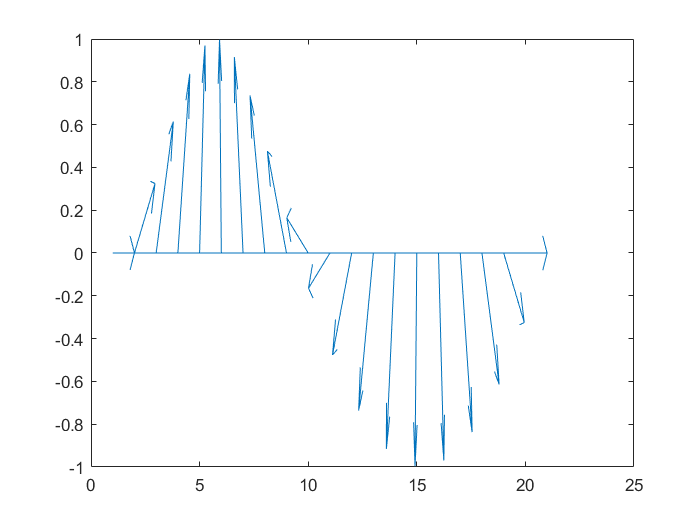

theta=linspace(0, 2*pi, 20); 
z = cos(theta)+i*sin(theta); 
feather(z); 

6、compass和feather很接近，只是每个箭号的起点都在圆点： 

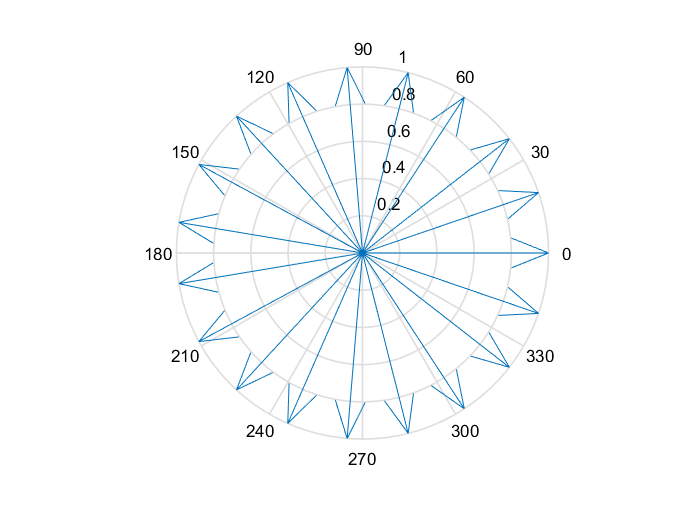

theta=linspace(0, 2*pi, 20); 
z = cos(theta)+i*sin(theta); 
compass(z); 

特殊的三维图形函数

空间等值线图： 

contour 3(x,y,z,n) 其中n表示等值线数。

例 山峰的三维和二维等值线图。

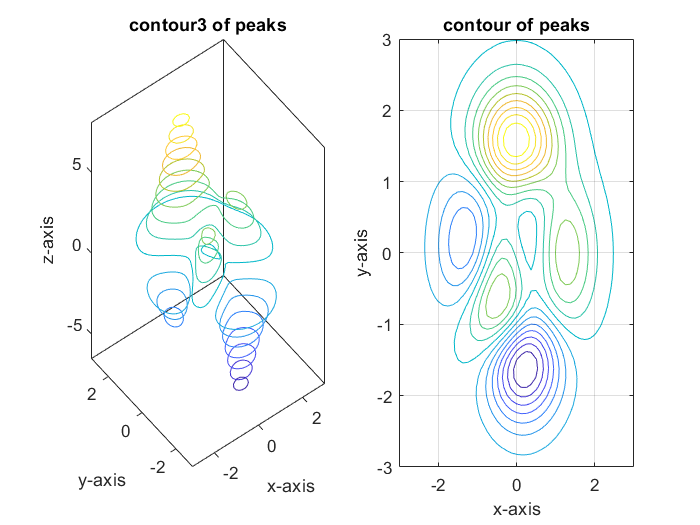

[x,y,z]=peaks;
subplot(1,2,1)       
contour3(x,y,z,16,'s')   
grid, xlabel('x-axis'), ylabel('y-axis')
zlabel('z-axis')
title('contour3 of peaks'); 
subplot(1,2,2)
contour(x,y,z,16,'s')
grid,   xlabel('x-axis'),    ylabel('y-axis')
title('contour of peaks');